

Figure = V1


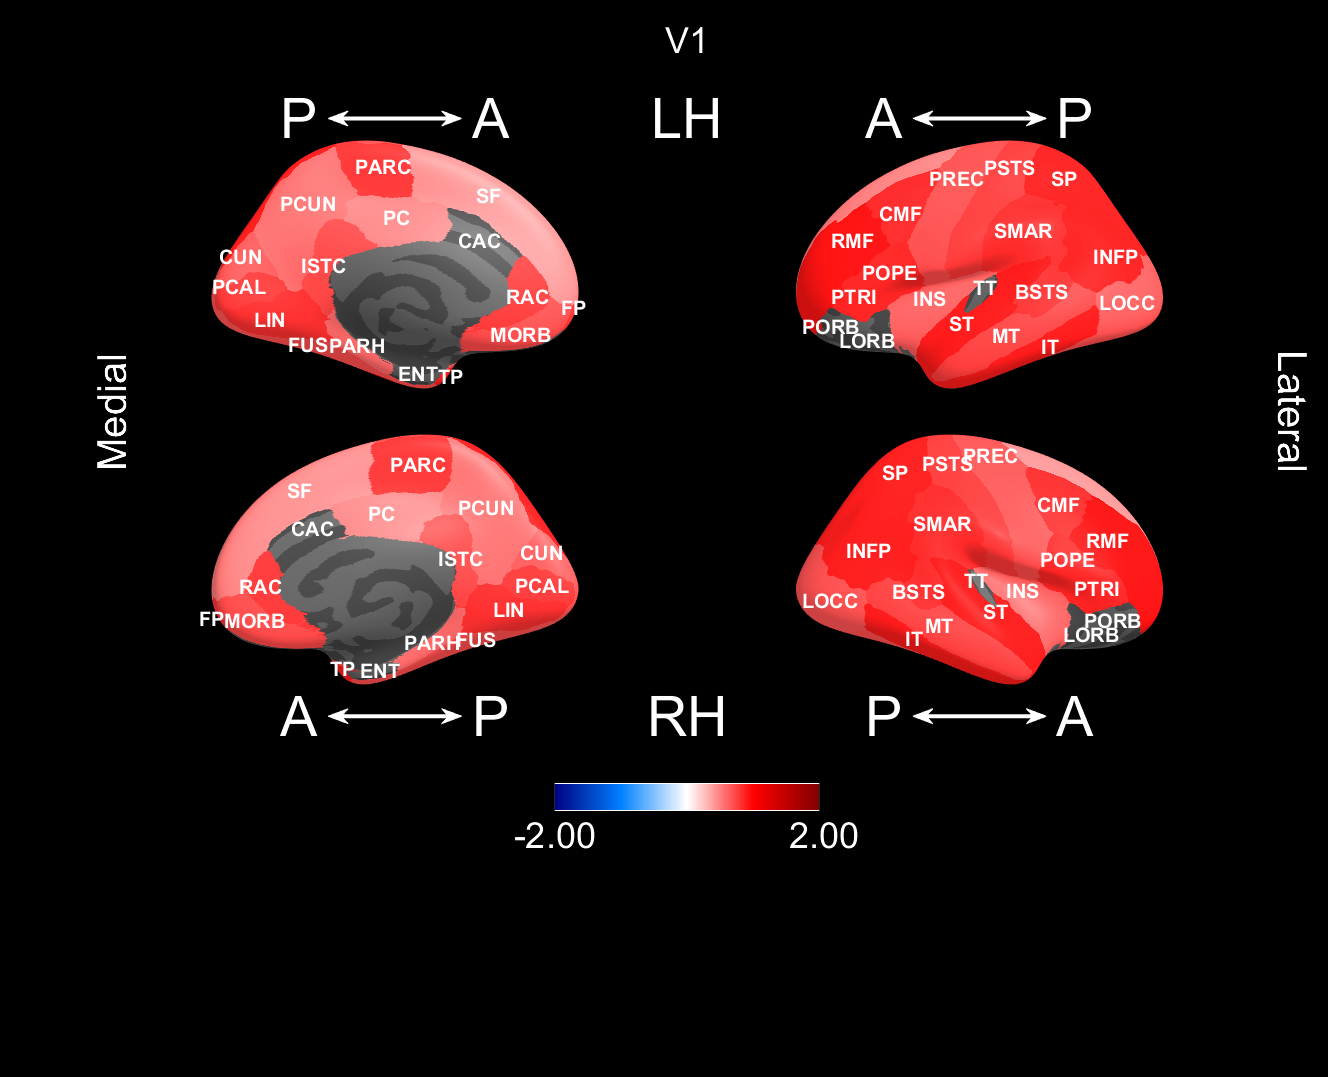

BSTS: Bank of STS, CAC: Caudal anterior cingulate, CMF: Caudal middle frontal, CUN: Cuneus, ENT: Entorhinal, FP: Frontal pole, FUS: Fusiform, INFP: Inferior parietal, INS: Insula, ISTC: Isthmus cingulate, IT: Inferior temporal, LIN: Lingual, LOCC: Lateral occipital, LORB: Lateral orbito-frontal, MORB: Medial orbito-frontal, MT: Middle temporal, PARC: Paracentral lobule, PARH: Parahippocampal, PC: Posterior cingulate, PCAL: Pericalcarine, PCUN: Precuneus, POPE: Pars opercularis, PORB: Pars orbitalis, PREC: Precentral, PSTS: Postcentral, PTRI: Pars triangularis, RAC: Rostral anterior cingulate, RMF: Rostral middle frontal, SF: Superior frontal, SMAR: Supramarginal, SP: Superior parietal, ST: Superior temporal, TP: Temporal pole, TT: Transverse temporal




Figure = V2


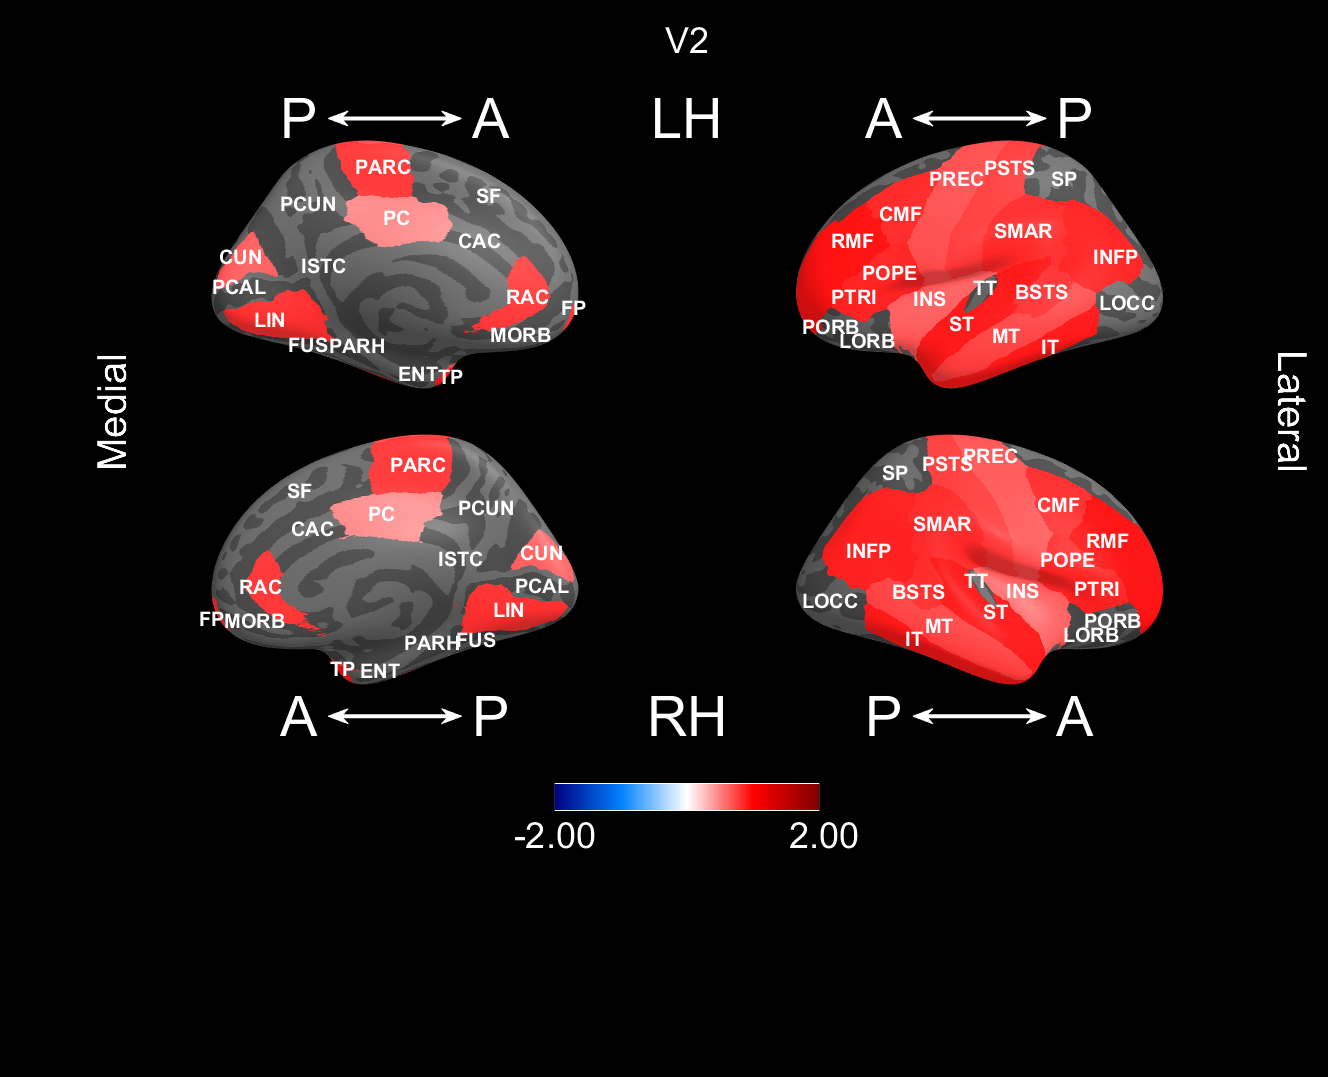

BSTS: Bank of STS, CAC: Caudal anterior cingulate, CMF: Caudal middle frontal, CUN: Cuneus, ENT: Entorhinal, FP: Frontal pole, FUS: Fusiform, INFP: Inferior parietal, INS: Insula, ISTC: Isthmus cingulate, IT: Inferior temporal, LIN: Lingual, LOCC: Lateral occipital, LORB: Lateral orbito-frontal, MORB: Medial orbito-frontal, MT: Middle temporal, PARC: Paracentral lobule, PARH: Parahippocampal, PC: Posterior cingulate, PCAL: Pericalcarine, PCUN: Precuneus, POPE: Pars opercularis, PORB: Pars orbitalis, PREC: Precentral, PSTS: Postcentral, PTRI: Pars triangularis, RAC: Rostral anterior cingulate, RMF: Rostral middle frontal, SF: Superior frontal, SMAR: Supramarginal, SP: Superior parietal, ST: Superior temporal, TP: Temporal pole, TT: Transverse temporal




Figure = V3


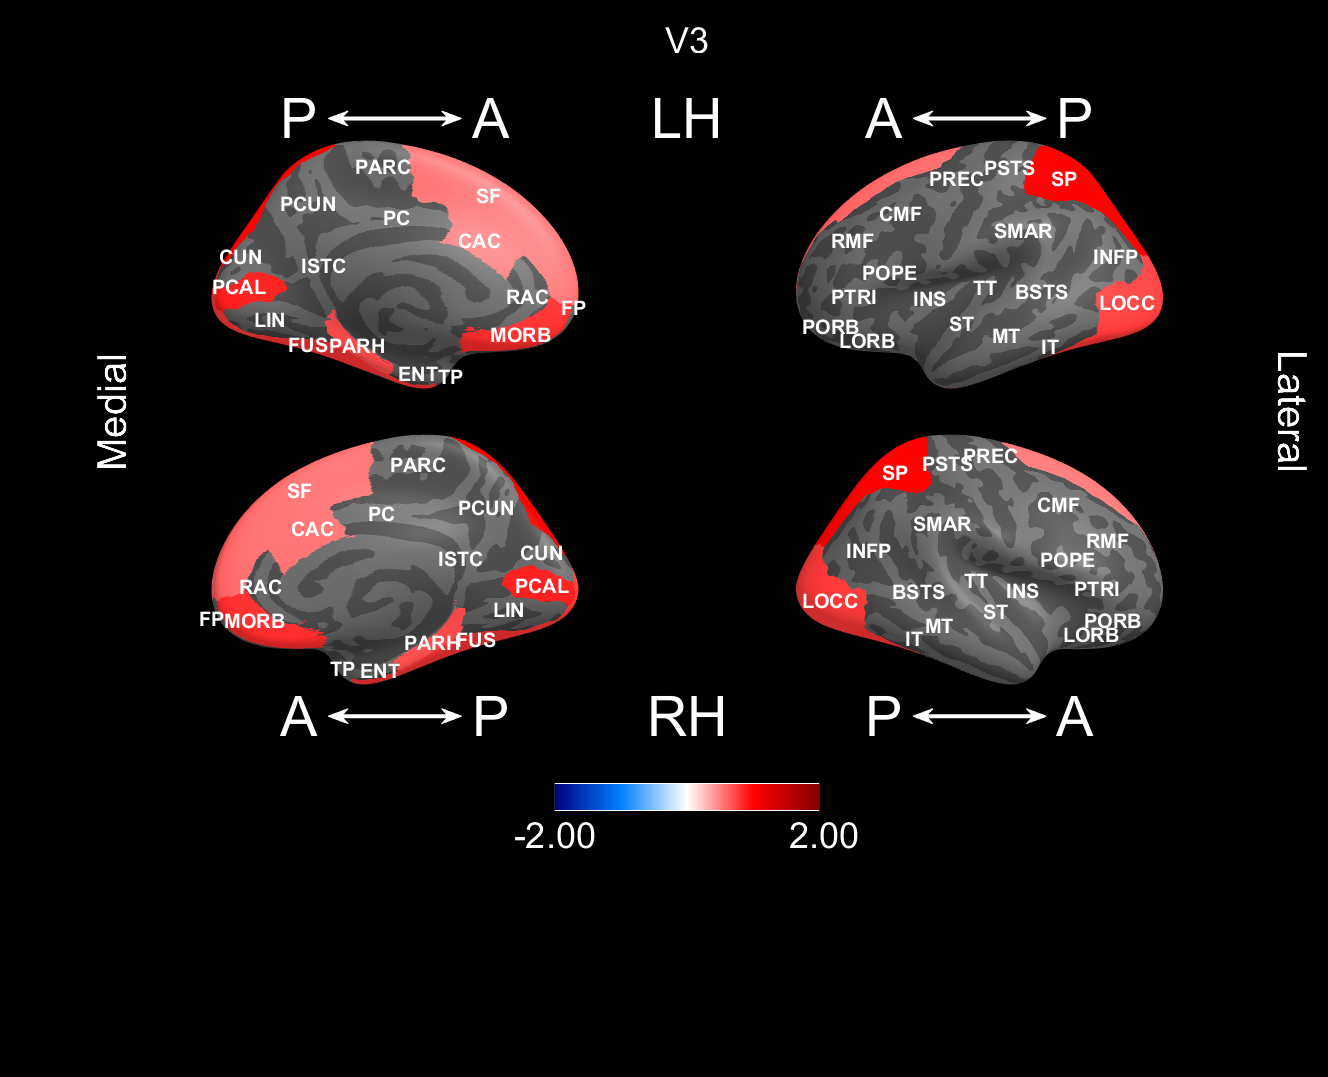

BSTS: Bank of STS, CAC: Caudal anterior cingulate, CMF: Caudal middle frontal, CUN: Cuneus, ENT: Entorhinal, FP: Frontal pole, FUS: Fusiform, INFP: Inferior parietal, INS: Insula, ISTC: Isthmus cingulate, IT: Inferior temporal, LIN: Lingual, LOCC: Lateral occipital, LORB: Lateral orbito-frontal, MORB: Medial orbito-frontal, MT: Middle temporal, PARC: Paracentral lobule, PARH: Parahippocampal, PC: Posterior cingulate, PCAL: Pericalcarine, PCUN: Precuneus, POPE: Pars opercularis, PORB: Pars orbitalis, PREC: Precentral, PSTS: Postcentral, PTRI: Pars triangularis, RAC: Rostral anterior cingulate, RMF: Rostral middle frontal, SF: Superior frontal, SMAR: Supramarginal, SP: Superior parietal, ST: Superior temporal, TP: Temporal pole, TT: Transverse temporal


% Plot values on Freesurfer surface
% by Delin Sun, Duke University, 06-15-2021
% Please first set path for freesurfer_statsurf_display toolbox (https://developmentalimagingmcri.github.io/freesurfer_statsurf_display/using/)

%% Parameters
fdir = pwd; % path to the data_for_demo.csv
fname = 'data_for_demo.csv'; % data file name, column#1 = name of brain region, #2 = id of brain region, #3... = values to display

% load data
fn = fullfile(fdir, fname);
T = readtable(fn);
T = sortrows(T,2); % sort rows according to the id of brain regions

%% Plots
for j = 3:size(T,2) % per Value to display
    % setting input parameters for plot
    Values = cell(1, 2); % 1=left, 2=right
    ValuesMask = cell(1, 2); % 1=left, 2=right
    
    for z = 1:2 % 1=left, 2=right
        Values{z} = T{:,j};
        ValuesMask{z} = true(size(T,1), 1); % DK atlas has 34 regions per hemisphere
        % ValuesMask{z}: true = show the region, false = hide the region
        % But we can set ValuesMask all as true, and make Values{z} as NaN to hide the region
        ValuesName = T.Properties.VariableNames{j}; % Value names as the title of plots
    end
    
    % plot
    fprintf('\n\nFigure = %s\n',ValuesName);
    figure;
    freesurfer_statsurf_scalar(Values, ValuesMask, 'aparc', 'MainTitle',ValuesName, 'UseShortLabels',true, 'ValueLimits',[-2 2])
    % 'aparc': Desikan-Killiany, 34 regions per hemisphere
    % 'dkt' : Desikan-Killiany-Tourville, 31 regions per hemisphere
    % 'aparc.a2009s' : Destreiux, 75 regions per hemisphere
    % 'ValueLimits', default is to use the min and max values of the Value of interest
end